8.2 8.3 has been done in lab 7

## 8.4

clc,clear,close all;
wp = 1.8;
ws = 2.2;
delta_p = 0.05;
delta_s = 0.005;
[n, fo, ao, w] = firpmord([wp ws], [1 0], [delta_p delta_s], 2*pi)

n = 25

fo =          0
    0.5730
    0.7003
    1.0000


ao =      1
     1
     0
     0


w =      1
    10


b = firpm(n, fo, ao, w)

b =    -0.0113    0.0032    0.0294    0.0017   -0.0175    0.0291    0.0078   -0.0477    0.0367    0.0469   -0.1210    0.0419    0.5282    0.5282    0.0419   -0.1210    0.0469    0.0367   -0.0477    0.0078    0.0291   -0.0175    0.0017    0.0294    0.0032   -0.0113


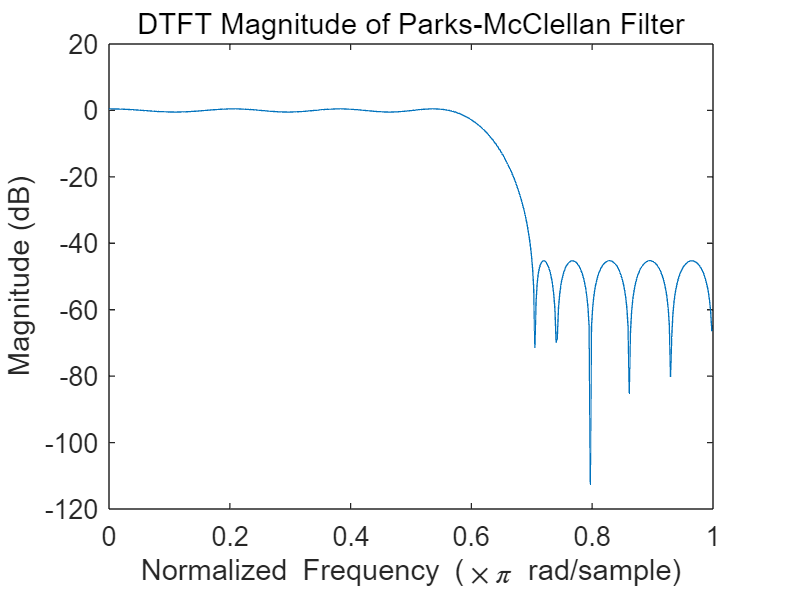

[H, w] = freqz(b, 1, 512, 2*pi);
figure;
plot(w/pi, 20*log10(abs(H)));
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
title('DTFT Magnitude of Parks-McClellan Filter');

magnitude decrease very quickly

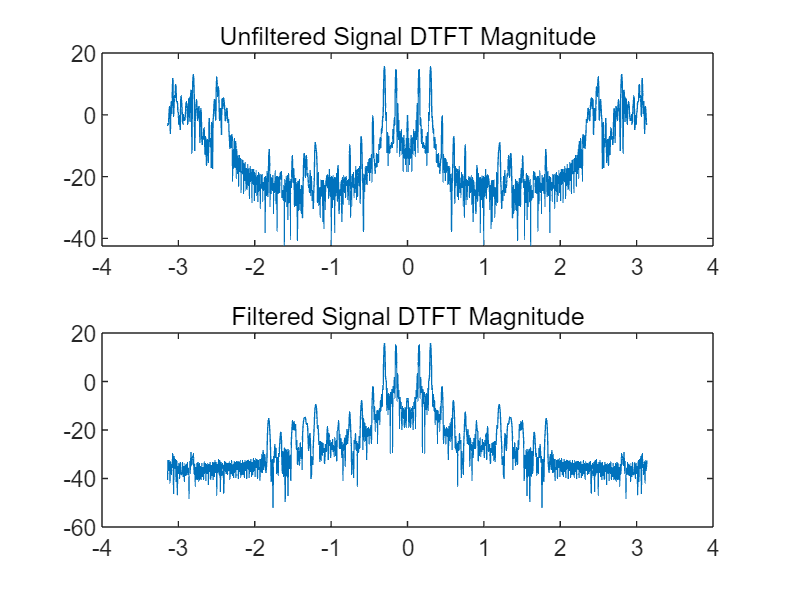

load nspeech2.mat;
filtered_signal = filter(b, 1, nspeech2);
dtft_points = 1024;
[H,w] = DTFT(nspeech2(20001:20400),dtft_points);
[Filtered_H, Filtered_w] = DTFT(filtered_signal(20001:20400), dtft_points);
figure;
subplot(211),plot(w, 20*log10(abs(H))),title('Unfiltered Signal DTFT Magnitude');
subplot(212),plot(Filtered_w, 20*log10(abs(Filtered_H))),title('Filtered Signal DTFT Magnitude');

sound(nspeech2, 8000);
pause(length(nspeech2) / 8000);
sound(filtered_signal, 8000);

the sound can be heard after filter